# **IBMs for Rapid Prototyping - Post Processing**

For processing exported data

## Load simDataStore.m file:

loadedFile = "C:\Users\georg\OneDrive - Loughborough University\_Y4\FYP\MATLAB\RW-05-IBM-for-Rapid-Prototyping\save_2026-04-09_00-06-17\SimulationData_2026-04-09_00-06-17.mat";
fieldType = "Full";
if fieldType == "Post Transient"
    U = simdataVariable.fieldAvgPostTransient;
    settlingTime = 0.3;
elseif fieldType == "Full"
    U = simdataVariable.fieldAvg;
end
[rho, u, v, p] = deal(U(:,:,1), U(:,:,2), U(:,:,3), U(:,:,4));
[X, Y] = deal(simdataVariable.meshGridXY(:,:,1), simdataVariable.meshGridXY(:,:,2));
[xGeo, yGeo]  = deal(simdataVariable.geometryData.XYGeometry(:,1), simdataVariable.geometryData.XYGeometry(:,2));
[rho0, U0, V0, p0] = deal(simdataVariable.freestreamConditions(1), simdataVariable.freestreamConditions(2), simdataVariable.freestreamConditions(3), simdataVariable.freestreamConditions(4));

Index exceeds the number of array elements. Index must not exceed 0.

simdataVariable.freestreamConditions = freestreamConditions;

## Interpolate Field:

[rho, u, v, p] = deal(U(:,:,1), U(:,:,2), U(:,:,3), U(:,:,4));
[X, Y] = deal(simdataVariable.meshGridXY(:,:,1), simdataVariable.meshGridXY(:,:,2));
[xGeo, yGeo]  = deal(simdataVariable.geometryData.XYGeometry(:,1), simdataVariable.geometryData.XYGeometry(:,2));
[rho0, U0, V0, p0] = deal(simdataVariable.freestreamConditions(1), simdataVariable.freestreamConditions(2), simdataVariable.freestreamConditions(3), simdataVariable.freestreamConditions(4));

Lx = max(X,[],'all'); Ly = max(Y,[],'all');    % domain size
[Ny, Nx] = size(X);
usFactor = 5; % upscale factor
Ny = Ny * usFactor; Nx = Nx * usFactor; 
dx = Lx / Nx; dy = Ly / Ny; % grid spacing (x,y)
x = linspace(dx/2, Lx-dx/2, Nx);
y = linspace(dy/2, Ly-dy/2, Ny);
[interpolatedGridX, interpolatedGridY] = meshgrid(x, y);

rho = interp2(X, Y, rho, interpolatedGridX, interpolatedGridY);
u = interp2(X, Y, u, interpolatedGridX, interpolatedGridY);
v = interp2(X, Y, v, interpolatedGridX, interpolatedGridY);
p = interp2(X, Y, p, interpolatedGridX, interpolatedGridY);

X = interpolatedGridX;
Y = interpolatedGridY;

## Force Coefficients:

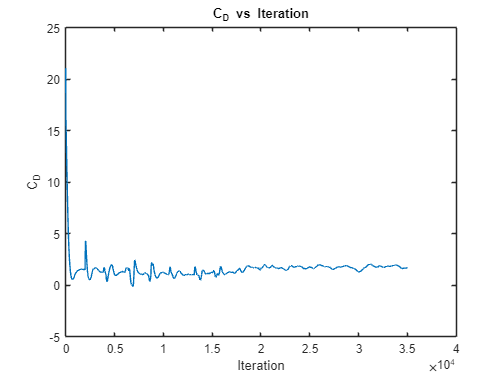

plot(simdataVariable.coefficients(:,1))
hold on
title("C_D vs Iteration")
xlabel("Iteration")
ylabel("C_D")
hold off

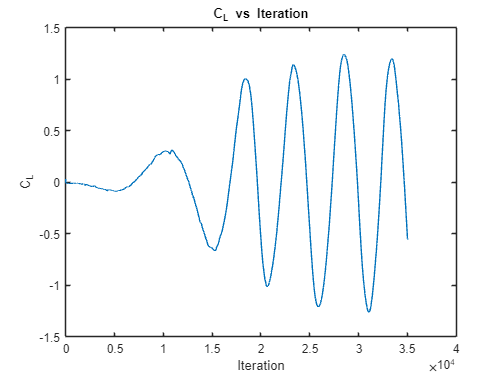


plot(simdataVariable.coefficients(:,2))
hold on
title("C_L vs Iteration")
xlabel("Iteration")
ylabel("C_L")
hold off

## Boundary Location:

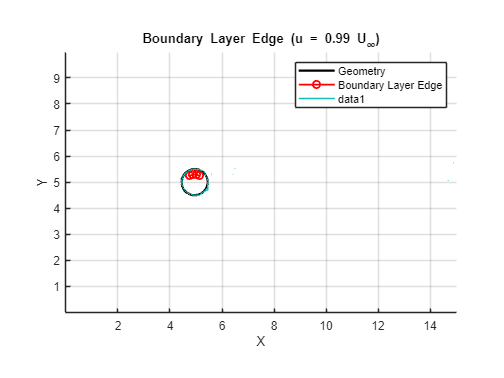

% find low velocity contour (approx. boundary location)
% level = 0.001;
% velocityMag = sqrt(u.^2 + v.^2);
% 
% Bloc = contour(X, Y, velocityMag, [level*U0 level*U0]);
% [BLocX, BlocY] = deal(Bloc(1,:)', Bloc(2,:)');
% 
% hold on
% plot(xGeo, yGeo,"r--")
% xlim([min(xGeo)*0.75 max(xGeo)*1.25]);
% ylim([min(yGeo)*0.75 max(yGeo)*1.25]);
% hold off
% 
% % True geometry
% tGeo = linspace(0,1,length(xGeo));
% 
% % Contour (perceived)
% tC = linspace(0,1,length(BLocX));
% 
% % Common parameter space
% tCommon = linspace(0,1,1000);
% 
% % interpolate curves
% xGeo_i = interp1(tGeo, xGeo, tCommon, 'linear');
% yGeo_i = interp1(tGeo, yGeo, tCommon, 'linear');
% 
% xB_i = interp1(tC, BLocX, tCommon, 'linear');
% yB_i = interp1(tC, BlocY, tCommon, 'linear');
% 
% % compute distances
% dist = sqrt((xGeo_i - xB_i).^2 + (yGeo_i - yB_i).^2);
% 
% % Calculate RMSE
% rmse_val = rmse(dist, zeros(size(dist)))


%% --- USER INPUTS ---
levelFactor = 0.01;   % threshold factor (velocity = levelFactor * U0)
nInterp = 1000;        % number of interpolation points

%% --- COMPUTE VELOCITY MAGNITUDE ---
velocityMag = sqrt(u.^2 + v.^2);
level = levelFactor * U0;

%% --- EXTRACT CONTOURS ---
C = contour(X, Y, velocityMag, [level level]);


%% --- PARAMETERIZE TRUE GEOMETRY ---
tGeo = linspace(0,1,length(xGeo));
tCommon = linspace(0,1,nInterp);

xGeo_i = interp1(tGeo, xGeo, tCommon, 'linear');
yGeo_i = interp1(tGeo, yGeo, tCommon, 'linear');

%% --- INITIALIZE ---
idx = 1;
best_rmse = inf;

%% --- LOOP THROUGH ALL CONTOUR SEGMENTS ---
while idx < size(C,2)
    
    % Number of points in this segment
    nPoints = C(2,idx);
    
    % Extract this contour segment
    xB = C(1, idx+1:idx+nPoints)';
    yB = C(2, idx+1:idx+nPoints)';
    
    % Skip very small segments (noise)
    if nPoints < 20
        idx = idx + nPoints + 1;
        continue
    end
    
    % Parameterize contour
    tB = linspace(0,1,length(xB));
    
    % Interpolate contour
    xB_i = interp1(tB, xB, tCommon, 'linear');
    yB_i = interp1(tB, yB, tCommon, 'linear');
    
    % --- ALIGN CURVES VIA CIRCULAR SHIFT ---
    min_rmse_segment = inf;
    
    for shift = 1:length(xB_i)
        x_shifted = circshift(xB_i, shift);
        y_shifted = circshift(yB_i, shift);
        
        % Distance between curves
        dist = sqrt((xGeo_i - x_shifted).^2 + (yGeo_i - y_shifted).^2);
        
        % RMSE using MATLAB function
        val = rmse(dist, zeros(size(dist)));
        
        if val < min_rmse_segment
            min_rmse_segment = val;
        end
    end
    
    % Store best RMSE across all segments
    if min_rmse_segment < best_rmse
        best_rmse = min_rmse_segment;
        
        % Store best matching contour for plotting
        best_xB = xB_i;
        best_yB = yB_i;
    end
    
    % Move to next contour segment
    idx = idx + nPoints + 1;
end

%% --- FINAL RESULT ---
rmse_val = best_rmse;

fprintf('Final RMSE = %.4f\n', rmse_val);

Final RMSE = 0.6985


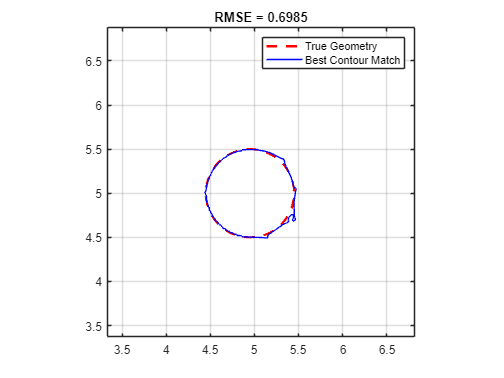


%% --- PLOT FOR VERIFICATION ---
figure;
plot(xGeo_i, yGeo_i, 'r--', 'LineWidth', 2); hold on;
plot(best_xB, best_yB, 'b-', 'LineWidth', 0.5);
axis equal
legend('True Geometry', 'Best Contour Match');
title(sprintf('RMSE = %.4f', rmse_val));

xlim([min(xGeo)*0.75 max(xGeo)*1.25]);
ylim([min(yGeo)*0.75 max(yGeo)*1.25]);
grid on; hold off;

## Boundary Layer (flat plate):

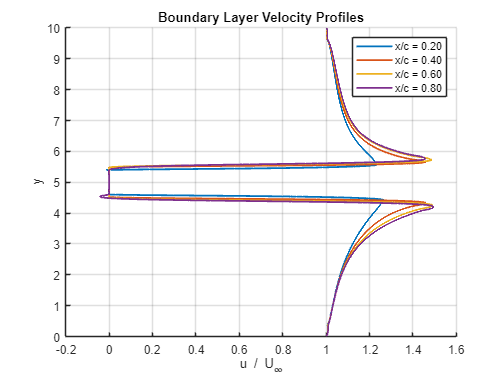


% Characteristic length (chord / plate length)
c = max(xGeo) - min(xGeo);

% Convert to physical x locations
xTargets = min(xGeo) + xOverC * c;

% Storage structure
BL = struct();

figure; hold on;

for i = 1:length(xTargets)
    
    % --- Find closest x location in grid ---
    [~, idx] = min(abs(X(1,:) - xTargets(i)));
    
    % --- Extract vertical profile ---
    x_line = X(:, idx);
    y_line = Y(:, idx);
    u_line = u(:, idx);
    
    % --- Sort by y (important for profiles) ---
    [y_sorted, sortIdx] = sort(y_line);
    u_sorted = u_line(sortIdx);
    
    % --- Remove NaNs ---
    valid = ~isnan(u_sorted);
    y_sorted = y_sorted(valid);
    u_sorted = u_sorted(valid);
    
    % --- Normalize velocity using freestream ---
    u_norm = u_sorted / U0;
    
    % --- Store data ---
    BL(i).xOverC = xOverC(i);
    BL(i).x = xTargets(i);
    BL(i).y = y_sorted;
    BL(i).u = u_sorted;
    BL(i).u_norm = u_norm;
    
    % --- Plot ---
    plot(u_norm, y_sorted, 'LineWidth', 1.5, ...
        'DisplayName', sprintf('x/c = %.2f', xOverC(i)));
end

xlabel('u / U_\infty');
ylabel('y');
title('Boundary Layer Velocity Profiles');
legend show;
grid on;

## Boundary Layer (General):

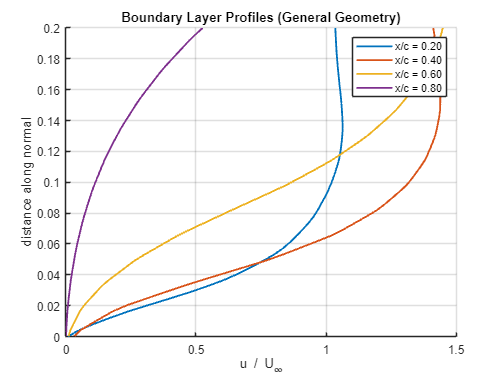

%% --- BOUNDARY LAYER PROFILES (GENERAL GEOMETRY) ---

% Characteristic length (chord / plate length)
c = max(xGeo) - min(xGeo);

% Define x/c locations
xOverC = [0.2, 0.4, 0.6, 0.8];

% Example surface points (can be anywhere)
xSurf = xOverC * c + min(xGeo);   % x locations
[xGeo_unique, idx_unique] = unique(xGeo);
yGeo_unique = yGeo(idx_unique);
ySurf = interp1(xGeo_unique, yGeo_unique, xSurf);
nPoints = 50;                                % points along normal
normalLength = 0.2 * c;                     % max distance along normal

% Storage
BL_general = struct();
figure; hold on;

for i = 1:length(xSurf)
    
    % --- Approximate local tangent ---
    [~, idxGeo] = min(abs(xGeo - xSurf(i)));
    if idxGeo == 1
        dx = xGeo(idxGeo+1) - xGeo(idxGeo);
        dy = yGeo(idxGeo+1) - yGeo(idxGeo);
    else
        dx = xGeo(idxGeo) - xGeo(idxGeo-1);
        dy = yGeo(idxGeo) - yGeo(idxGeo-1);
    end
    tangent = [dx, dy] / norm([dx, dy]);
    
    % --- Normal pointing outward (toward fluid) ---
    center_x = mean(xGeo); center_y = mean(yGeo);
    normal = [xSurf(i) - center_x, ySurf(i) - center_y]; 
    normal = normal / norm(normal);  % unit vector
    
    % --- Points along normal ---
    s = linspace(0, normalLength, nPoints);
    x_line = xSurf(i) + normal(1) * s;
    y_line = ySurf(i) + normal(2) * s;
    
    % --- Interpolate velocity along normal ---
    u_line = interp2(X, Y, u, x_line, y_line);
    u_norm = u_line / U0;
    
    % --- Flip normal if velocity decreases along normal ---
    if u_norm(1) > u_norm(end)
        normal = -normal;
        x_line = xSurf(i) + normal(1) * s;
        y_line = ySurf(i) + normal(2) * s;
        u_line = interp2(X, Y, u, x_line, y_line);
        u_norm = u_line / U0;
    end
    
    % --- Store ---
    BL_general(i).xSurf = xSurf(i);
    BL_general(i).ySurf = ySurf(i);
    BL_general(i).x_line = x_line;
    BL_general(i).y_line = y_line;
    BL_general(i).u_line = u_line;
    BL_general(i).u_norm = u_norm;
    
    % --- Plot ---
    plot(u_norm, s, 'LineWidth', 1.5, 'DisplayName', sprintf('x/c = %.2f', xOverC(i)));
end

xlabel('u / U_\infty'); ylabel('distance along normal'); title('Boundary Layer Profiles (General Geometry)'); legend show; grid on;

## Plot BL profiles over geometry (WIP):

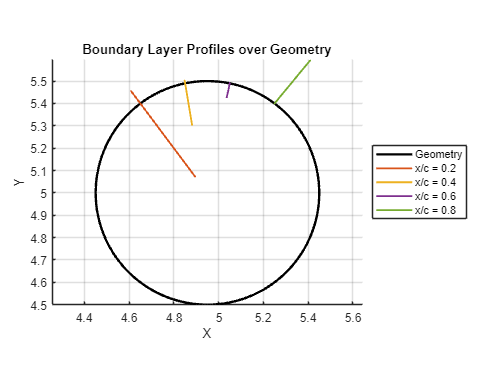

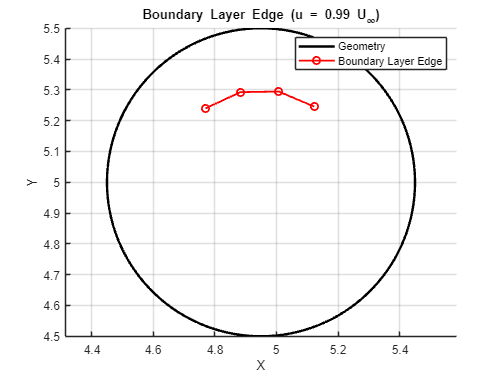

%% --- PLOT VELOCITY PROFILES OVER GEOMETRY ---

figure; hold on; axis equal;

% Plot geometry
plot(xGeo, yGeo, 'k-', 'LineWidth', 2, 'DisplayName', 'Geometry');

% Scaling factor for visualization (adjust to your preference)
scale = 2000 * c;  % how far to extend profiles in x/y for plotting

% Loop over all profiles
for i = 1:length(BL_general)
    
    % Extract normal vector for plotting
    xSurf_i = BL_general(i).xSurf;
    ySurf_i = BL_general(i).ySurf;
    x_line = BL_general(i).x_line;
    y_line = BL_general(i).y_line;
    u_norm = BL_general(i).u_norm;
    
    % Vector along normal scaled by velocity
    x_plot = xSurf_i + (x_line - xSurf_i) .* u_norm * scale;
    y_plot = ySurf_i + (y_line - ySurf_i) .* u_norm * scale;
    
    % Plot profile
    plot(x_plot, y_plot, 'LineWidth', 1.5, 'DisplayName', sprintf('x/c = %.2f', xOverC));
end

xlabel('X'); ylabel('Y');
title('Boundary Layer Profiles over Geometry');
legend('Geometry',['x/c = ' num2str(xOverC(1))], ['x/c = ' num2str(xOverC(2))], ['x/c = ' num2str(xOverC(3))], ['x/c = ' num2str(xOverC(4))], "Location", "eastoutside");
grid on;